clc;
clear all

syms R1 R2 R3 R4 R5 R6 R7 C1 C2 H1 H2 H3 Ho s
H1=R2/R1/(R2*C1*s+1); 
H2=R4/R3/(C2*s*R4+1); 
H3=R6/R5/R7; 
Ho=H1*H2/(1+H1*H2*H3); 
Ho=collect(simplify(expand(Ho)),'s') 

$$Ho = \frac{R_{2}\,R_{4}\,R_{5}\,R_{7}}{\left(C_{1}\,C_{2}\,R_{1}\,R_{2}\,R_{3}\,R_{4}\,R_{5}\,R_{7}\right)\,s^{2}+\left(C_{1}\,R_{1}\,R_{2}\,R_{3}\,R_{5}\,R_{7}+C_{2}\,R_{1}\,R_{3}\,R_{4}\,R_{5}\,R_{7}\right)\,s+R_{2}\,R_{4}\,R_{6}+R_{1}\,R_{3}\,R_{5}\,R_{7}}$$

pretty(Ho)

                                          R2 R4 R5 R7
-----------------------------------------------------------------------------------------------
                         2
C1 C2 R1 R2 R3 R4 R5 R7 s  + (C1 R1 R2 R3 R5 R7 + C2 R1 R3 R4 R5 R7) s + R2 R4 R6 + R1 R3 R5 R7




R7=1000; R6=R7; R5=R6; R4=R5; R3=R4; R2=R3; R1=R2;
C1=1e-6; C2=C1;

num = [R2*R4*R5*R7];
den = [(C1*C2*R1*R2*R3*R4*R5*R7) (C1*R1*R2*R3*R5*R7+C2*R1*R3*R4*R5*R7) (R2*R4*R6+R1*R3*R5*R7)];
Ho = tf(num, den);
step(Ho);
hold on
R2=100;
num = [R2*R4*R5*R7];
den = [(C1*C2*R1*R2*R3*R4*R5*R7) (C1*R1*R2*R3*R5*R7+C2*R1*R3*R4*R5*R7) (R2*R4*R6+R1*R3*R5*R7)];
Ho = tf(num, den);
step(Ho);
stepinfo(Ho)

ans = struct with fields:
         RiseTime: 0.0022
    TransientTime: 0.0040
     SettlingTime: 0.0040
      SettlingMin: 0.0900
      SettlingMax: 0.0999
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0999
         PeakTime: 0.0074



R2=300;
num = [R2*R4*R5*R7];
den = [(C1*C2*R1*R2*R3*R4*R5*R7) (C1*R1*R2*R3*R5*R7+C2*R1*R3*R4*R5*R7) (R2*R4*R6+R1*R3*R5*R7)];
Ho = tf(num, den);
step(Ho);
stepinfo(Ho)

ans = struct with fields:
         RiseTime: 0.0024
    TransientTime: 0.0043
     SettlingTime: 0.0043
      SettlingMin: 0.2706
      SettlingMax: 0.2996
        Overshoot: 0
       Undershoot: 0
             Peak: 0.2996
         PeakTime: 0.0072



R2=500;
num = [R2*R4*R5*R7];
den = [(C1*C2*R1*R2*R3*R4*R5*R7) (C1*R1*R2*R3*R5*R7+C2*R1*R3*R4*R5*R7) (R2*R4*R6+R1*R3*R5*R7)];
Ho = tf(num, den);
step(Ho);
stepinfo(Ho)

ans = struct with fields:
         RiseTime: 0.0026
    TransientTime: 0.0046
     SettlingTime: 0.0046
      SettlingMin: 0.4509
      SettlingMax: 0.4993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.4993
         PeakTime: 0.0078



R2=800;
num = [R2*R4*R5*R7];
den = [(C1*C2*R1*R2*R3*R4*R5*R7) (C1*R1*R2*R3*R5*R7+C2*R1*R3*R4*R5*R7) (R2*R4*R6+R1*R3*R5*R7)];
Ho = tf(num, den);
step(Ho);
stepinfo(Ho)

ans = struct with fields:
         RiseTime: 0.0030
    TransientTime: 0.0053
     SettlingTime: 0.0053
      SettlingMin: 0.7213
      SettlingMax: 0.7993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.7993
         PeakTime: 0.0119



R2=1000;
num = [R2*R4*R5*R7];
den = [(C1*C2*R1*R2*R3*R4*R5*R7) (C1*R1*R2*R3*R5*R7+C2*R1*R3*R4*R5*R7) (R2*R4*R6+R1*R3*R5*R7)];
Ho = tf(num, den);
step(Ho);
stepinfo(Ho)

ans = struct with fields:
         RiseTime: 0.0034
    TransientTime: 0.0058
     SettlingTime: 0.0058
      SettlingMin: 0.9014
      SettlingMax: 0.9989
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9989
         PeakTime: 0.0119



R2=3000;
num = [R2*R4*R5*R7];
den = [(C1*C2*R1*R2*R3*R4*R5*R7) (C1*R1*R2*R3*R5*R7+C2*R1*R3*R4*R5*R7) (R2*R4*R6+R1*R3*R5*R7)];
Ho = tf(num, den);
step(Ho);
stepinfo(Ho)

ans = struct with fields:
         RiseTime: 0.0071
    TransientTime: 0.0129
     SettlingTime: 0.0129
      SettlingMin: 2.6944
      SettlingMax: 2.9895
        Overshoot: 0
       Undershoot: 0
             Peak: 2.9895
         PeakTime: 0.0239



R2=5000;
num = [R2*R4*R5*R7];
den = [(C1*C2*R1*R2*R3*R4*R5*R7) (C1*R1*R2*R3*R5*R7+C2*R1*R3*R4*R5*R7) (R2*R4*R6+R1*R3*R5*R7)];
Ho = tf(num, den);
step(Ho);
stepinfo(Ho)

ans = struct with fields:
         RiseTime: 0.0113
    TransientTime: 0.0206
     SettlingTime: 0.0206
      SettlingMin: 4.4850
      SettlingMax: 4.9713
        Overshoot: 0
       Undershoot: 0
             Peak: 4.9713
         PeakTime: 0.0368



R2=8000;
num = [R2*R4*R5*R7];
den = [(C1*C2*R1*R2*R3*R4*R5*R7) (C1*R1*R2*R3*R5*R7+C2*R1*R3*R4*R5*R7) (R2*R4*R6+R1*R3*R5*R7)];
Ho = tf(num, den);
step(Ho);
stepinfo(Ho)

ans = struct with fields:
         RiseTime: 0.0177
    TransientTime: 0.0321
     SettlingTime: 0.0321
      SettlingMin: 7.1469
      SettlingMax: 7.9269
        Overshoot: 0
       Undershoot: 0
             Peak: 7.9269
         PeakTime: 0.0543


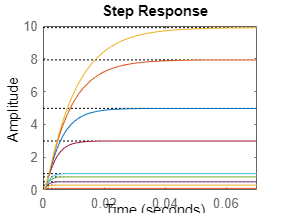


R2=10000;
num = [R2*R4*R5*R7];
den = [(C1*C2*R1*R2*R3*R4*R5*R7) (C1*R1*R2*R3*R5*R7+C2*R1*R3*R4*R5*R7) (R2*R4*R6+R1*R3*R5*R7)];
Ho = tf(num, den);
step(Ho);

stepinfo(Ho)

ans = struct with fields:
         RiseTime: 0.0219
    TransientTime: 0.0397
     SettlingTime: 0.0397
      SettlingMin: 8.9162
      SettlingMax: 9.8957
        Overshoot: 0
       Undershoot: 0
             Peak: 9.8957
         PeakTime: 0.0755



%Overshoot remains the same
%Settling time and transient time get bigger as R2 increases